Group Name:

Wednesday Group 1 - Lab 1 Submission

Tennison Liu 450224652

Jessie Zhang 480104780

Junhua Situ 450034626

# Lab 1

## Prepare

Please go through the live scripts: MatlabReview and BasicAudioImage.

## Q1. Sine Wave

Create a cosine wave with a frequency of 1 kHz, sampled at 48 kHz, with a duration of 0.5 seconds and 0 phase offset. Play the sine wave and listen to check that it is correct. Plot the first three periods of your cosine signal with the correct time axis. Label your plot and label the axes.

**Solution**

fs = 48000;
t = 0:1/fs:0.5;
f = 1000;
y = cos(2*pi*f*t);
three_period = 3*(fs/f);
disp(three_period);

   144



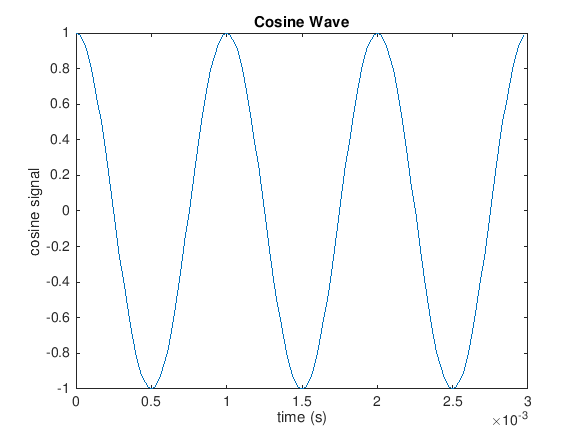

figure;
plot(t(1:three_period),y(1:three_period));
title('Cosine Wave')
xlabel('time (s)')
ylabel('cosine signal')

## Q2. Periodic Signals

The complex exponential sequence $e^{j\,\omega_0\,n}$ or the sinusoidal sequence $\cos(\omega_0\,n)$are periodic if the normalized frequency $f_0=\frac{\omega_0}{2\pi}$ is a rational number; that is $f_0 = \frac{K}{N}$, where K and N are integers.

- Prove the result (write your answer using Latex math style)

- Generate exp(j0.1$\pi$n), -100 < n < 100. Plot its real and imaginary parts using the stem function. Is this sequence periodic? If it is, what is the fundamental period? From the examination of the plot, what interpretation can you give to the integers K and N?

- Generate and plot cos(0.1n), 0 < n < 63. Is this sequence periodic? Plot the sequence for 63 < n < 126. Plot the difference between these two regions of the sequence

## Solution

1.A sequence is said to be periodic if $\mathrm{cos}\left(w_0 n\right)=\mathrm{cos}\left(w_0 \left(N+n\right)\right)$for an integer N. A sinusoidal sequence is periodic if ${\mathrm{Nw}}_o$ is an integer multiple of $2\pi$, we will call this integer multiple K. Therefore, $\mathrm{N2}\pi f_{0\;} =2K\pi$ and $f_{0\;} =\frac{K}{N}$, the frequency is the ratio of two rational integers, so the frequency must also be rational.

2.

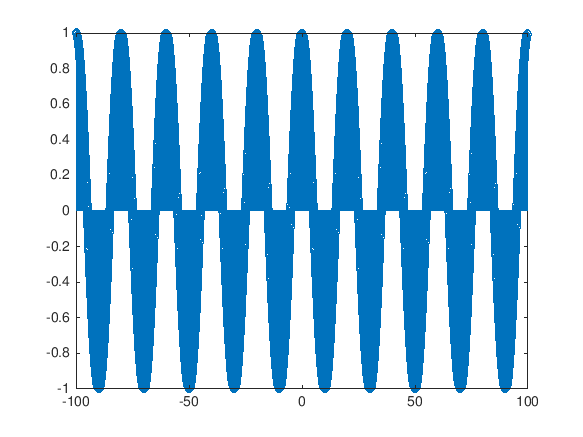

n = -100:0.01:100;
y = exp(i*0.1*pi*n);
stem(n, real(y));

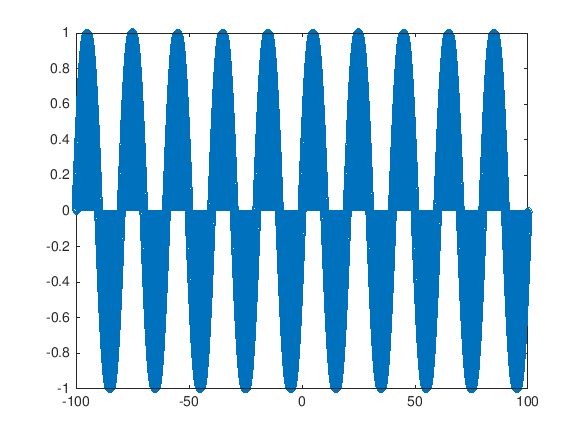

stem(n, imag(y));

The sequence is periodic. The fundamental period appears to be around 20. In this function, the $f_0 =\frac{\left(0\ldotp 1*\mathrm{pi}\right)}{2*\mathrm{pi}}=\frac{0\ldotp 1}{2}=0\ldotp 05\ldotp$ The period is thus $\frac{1}{f_0 }=\frac{1}{0\ldotp 05}=20$. We can view this as K = 1, and N = 0.05, this ratio is rational, so we have a periodic signal.

3.

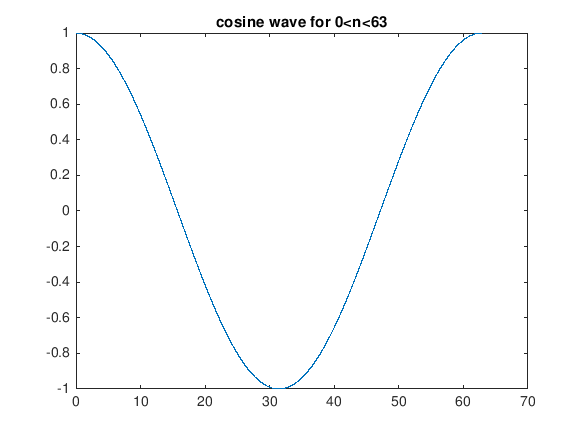

n_1 = 0:0.01:63;
y_1 = cos(0.1*n_1);
figure;
plot(n_1, y_1);
title('cosine wave for 0<n<63');

n_2 = 63:0.01:126;
figure;
y_2 = cos(0.1*n_2);

y_2 =     0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9996    0.9996    0.9996    0.9996    0.9995    0.9995    0.9995    0.9994    0.9994    0.9994    0.9993    0.9993    0.9992    0.9992    0.9992    0.9991    0.9991    0.9990    0.9990    0.9990    0.9989    0.9989    0.9988    0.9988    0.9987    0.9987    0.9986    0.9986    0.9985    0.9984    0.9984    0.9983    0.9983    0.9982    0.9982    0.9981    0.9980    0.9980    0.9979    0.9978


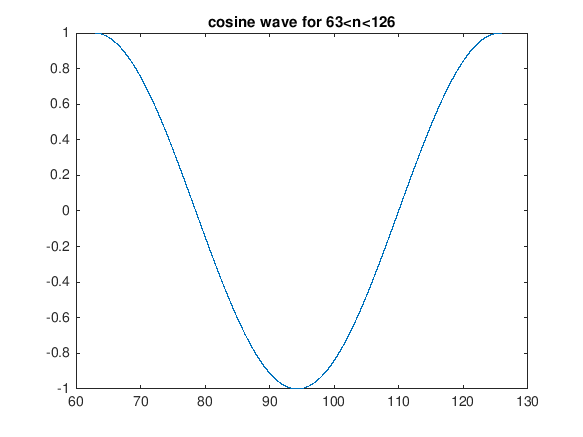

plot(n_2, y_2);
title('cosine wave for 63<n<126');

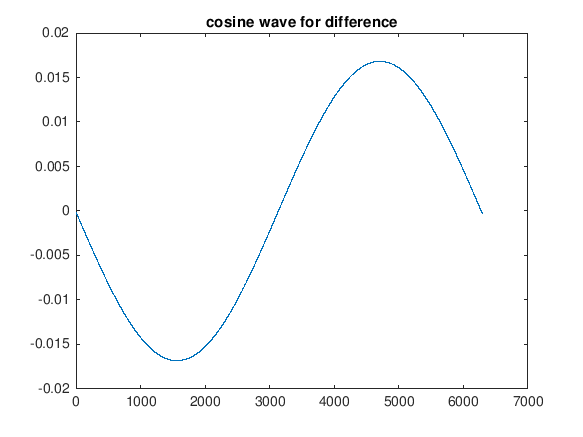

figure;
plot(y_2-y_1);
title('cosine wave for difference');

This sequence is not periodical. That is apparent because the difference in the two cosine waves is not zero. This is because $w_0 =0\ldotp 1$ and $f_0 =\frac{w_0 }{2*\mathrm{pi}}=\frac{0\ldotp 1}{2*\mathrm{pi}}$ is not rational. Therefore the signal is not periodic.

## Q3. Convolution

Write a MATLAB program that explicitly computes the convolution $y = x[n] * h[n]$of the following two sequences: x[n], h[n] (given below). Your program should employ a for loop and use the sigfold, sigshift, sigmult functions.

What is the value of y[4] ?

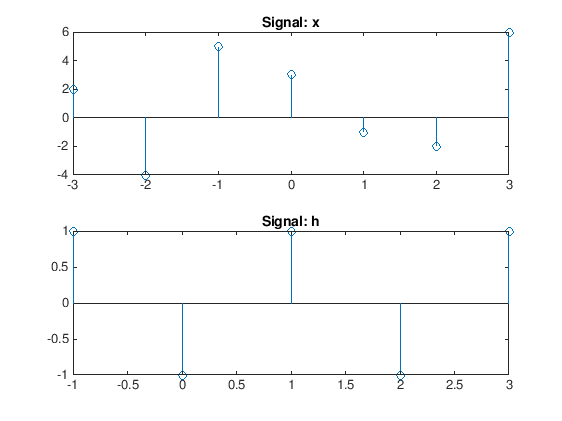

close all
nx = (-3:3) ;
x = [2,-4,5,3,-1,-2,6] ;
nh = (-1:3) ;
h = [1,-1,1,-1,1] ;
figure
set(gcf,'Visible','On')
subplot(2,1,1);
stem(nx,x);
title('Signal: x')
subplot(2,1,2)
stem(nh,h);
title('Signal: h')

## Solution

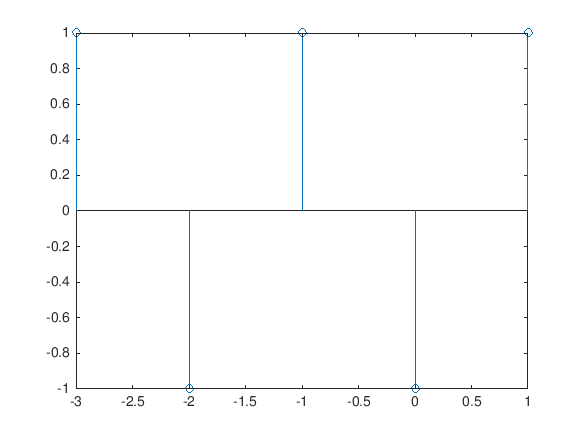

close all
% sigfold flips the signal on the x-axis
[hFold,nhF] = sigfold(h,nh);
stem(nhF, hFold);

ny = (-4:6);
% clearing and creating new array y
y = [];
for I = ny
    % sigshift shifts the signal hFold by I
    [hFShift, nShift] = sigshift(hFold, nhF, I) ;
    % sigmult implements y(n) = x1(n)*x2(n)
    y(I+5) = sum(sigmult(x,nx,hFShift,nShift)) ;
end
disp('ny = ');

ny = 


disp(size(ny));

     1    11



disp('y = ');

y = 


disp(size(y));

     1    11



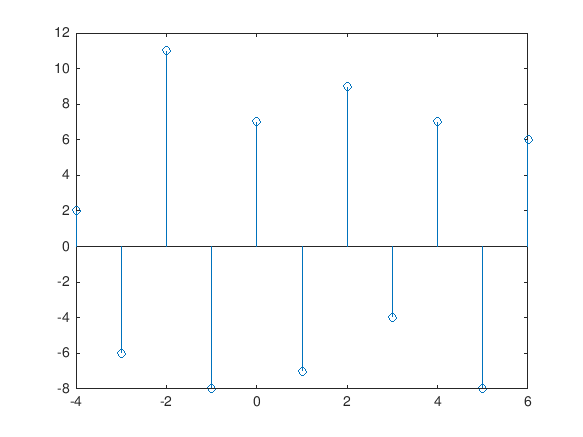

stem(ny,y);

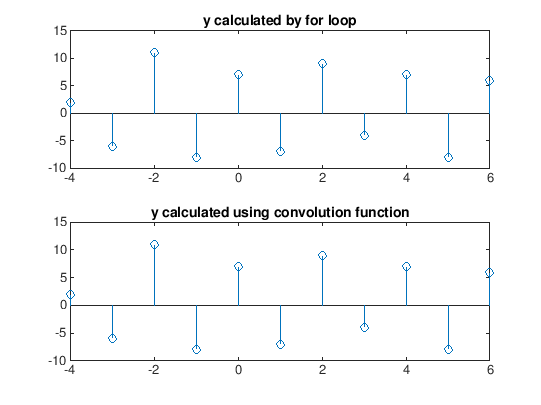

[y2, ny2] = conv_m(x,nx,h,nh);

figure;
set(gcf,'Visible','On');
subplot(2,1,1);
stem(ny,y);
title('y calculated by for loop');
subplot(2,1,2);
stem(ny2,y2);
title('y calculated using convolution function');


disp('The value of y[4] calculated by the convolution sum is:');

The value of y[4] calculated by the convolution sum is:


y_4 = y(9)

y_4 = 7

As shown in the stem graphs on the right. The convolution sum as implemented through a for loop achieves similar results as that calculated in the conv_m() function. The value of y[4] is 7.

## Q4. Convolution as a Matrix-Vector Operation

When sequences x[n] and h[n] are of finite duration, then their linear convolution y[n] = x[n] * h[n] can be implemented using matrix-vector multiplication. In this case, we let y[n] and x[n] be column vectors and we have:


$$y = \mathbf{H}\,x$$


where linear shifts in h[n-k] are arranged as rows in the matrix **H**. The matrix **H** has an interesting structure and is called a Toeplitz matrix.

To investigate these issues do the following:

- Let x[n] = {1,2,3,4,5} for n = {0,1,2,3,4} and h[n] = {6,7,8,9} for n = {0,1,2,3}. Determine the linear convolution, y[n], of these two sequences. You can use the conv_m function.

- Express x[n] as a column vector; y[n] as a column vector. Determine the matrix **H**..

- Characterize the matrix **H**.

- Describe the first column and first row of **H**.

- Complete the MATLAB function conv_tp.m Use the MATLAB function toeplitz.

## Solution

1.

nx, x, nh, h = [];

nx =      0     1     2     3     4


x =      1     2     3     4     5


nh =      0     1     2     3


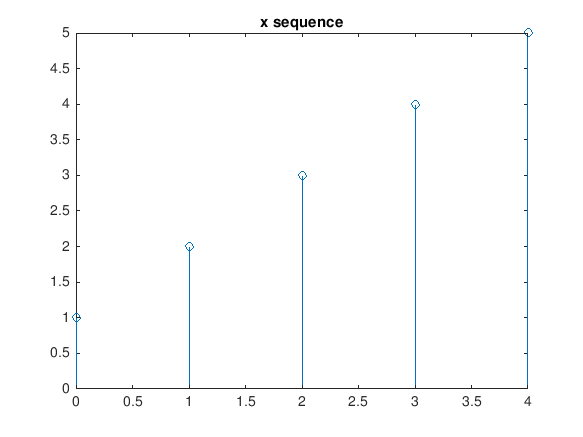

nx = (0:4) ;
x = [1, 2, 3, 4, 5] ;
nh = (0:3) ;
h = [6, 7, 8, 9] ;
stem(nx, x);
title('x sequence');

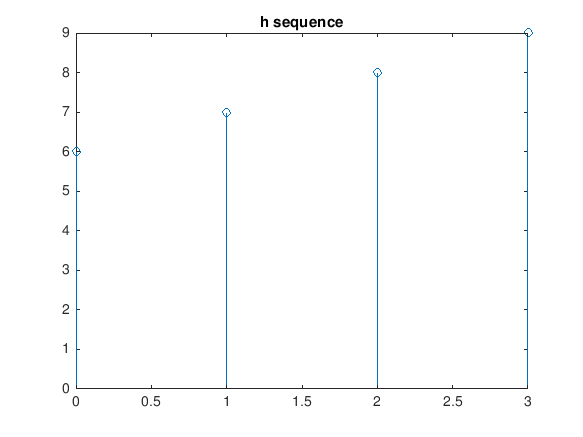


stem(nh, h);
title('h sequence');

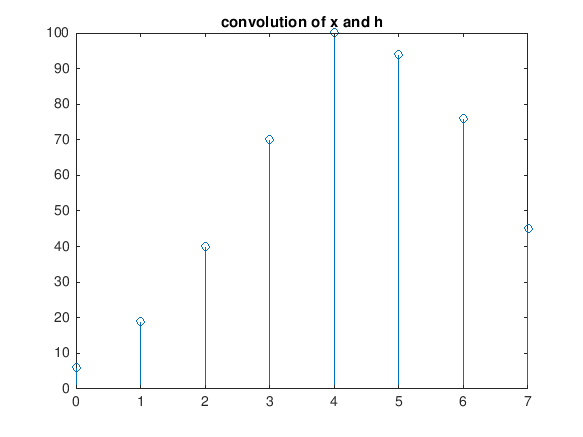


[y3, ny3] = conv_m(x,nx,h,nh);
stem(ny3, y3);
title('convolution of x and h');

2.

x_col = x';
y3_col = y3';
H = [6, 0, 0, 0, 0; 7, 6, 0, 0, 0; 8, 7, 6, 0, 0; 9, 8, 7, 6, 0; 
    0, 9, 8, 7, 6; 0, 0, 9, 8, 7; 0, 0, 0, 9, 8; 0, 0, 0, 0, 9]

H =      6     0     0     0     0
     7     6     0     0     0
     8     7     6     0     0
     9     8     7     6     0
     0     9     8     7     6
     0     0     9     8     7
     0     0     0     9     8
     0     0     0     0     9


h_times_xcol= H*x_col;
y3_col

y3_col =      6
    19
    40
    70
   100
    94
    76
    45


3.

H is a toeplitz matrix, it has constant values along all the negative sloping diagonals i.e. the descending diagonal from left to right is constant. This property can be seen in the matrix H above, whih has been printed. This matrix is significant because each row represents a linear shift in the h[n].

4.

The first column is h[n] with four zeros. The first row is h(1) and zeros. 

5.

ans_5 = conv_tp(h,x)

H =      6     0     0     0     0
     7     6     0     0     0
     8     7     6     0     0
     9     8     7     6     0
     0     9     8     7     6
     0     0     9     8     7
     0     0     0     9     8
     0     0     0     0     9


y =      6
    19
    40
    70
   100
    94
    76
    45


ans_5 =      6
    19
    40
    70
   100
    94
    76
    45


The conv_tp(h, x) function has been pasted and commented out below.

% 
% function [y,H] = conv_tp(h,x)
% % Linear Convolution using Toeplitz Matrix
% % -----------------------------------------
% % [y,H] = conv_tp(h,x)
% % y = output sequence in column format
% % H = Toeplitz convolution matrix
% % h = impulse response in column format
% % x = input sequence in column format
% col0 = [h'; zeros(length(x)-1, 1)];
% row0 = [h(1), zeros(1,length(x)-1)];
% H = toeplitz(col0,row0)
% y = H*x'